**Params**

fs = 48000;
N_FS_DEV = 4;
fsN=fs/N_FS_DEV;

num_bits = 23;

**Remove Silent part and Reduce the sampling rate**

preproc_data = {};
preproc_fi_data = {};

for d = 1: length(rec_data)
    ABELLPROVA2=cell2mat(rec_data(d));
    j=1;
    out_1 = zeros(length(ABELLPROVA2),1);
    
    for i=1:length(ABELLPROVA2)
        if rem(i,N_FS_DEV)==0
            out_1(j)=ABELLPROVA2(i);
            j=j+1;
        end
    end

    
    %Finding the starting point in order to remove silent part
    StartA=0;
    EndA=0;
    
    for i=1:length(out_1)
        if out_1(i)>0.05
            StartA=i;
            break;
        end
    end
    
    %Finding the end part and then reduce our data length
    for i=length(out_1):-1:1
        if out_1(i)>0.05
        EndA=i;
        break;
        end
    end
    out_2=out_1(StartA+20:EndA-20);
    preproc_data = [preproc_data, out_2];
    out_2 = convertToFixedPoint(out_2, num_bits);
    preproc_fi_data = [preproc_fi_data, out_2];
end 


**Test**

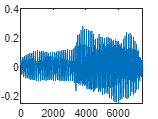

data_inx= 17;
sound(cell2mat(preproc_data(data_inx)),fsN);
plot(cell2mat(preproc_data(data_inx)))

sound(FixedPointToFloat(cell2mat(preproc_fi_data(data_inx)),num_bits),fsN);
plot(FixedPointToFloat(cell2mat(preproc_fi_data(data_inx)),num_bits))


cell_array = preproc_fi_data

cell_array = 1×30 cell array
    {5217×1 double}    {4368×1 double}    {4592×1 double}    {6506×1 double}    {5211×1 double}    {4639×1 double}    {5023×1 double}    {4771×1 double}    {5375×1 double}    {7379×1 double}    {3288×1 double}    {6196×1 double}    {3239×1 double}    {2552×1 double}    {5460×1 double}    {5987×1 double}    {7496×1 double}    {4675×1 double}    {4798×1 double}    {4791×1 double}    {4504×1 double}    {6116×1 double}    {6585×1 double}    {5801×1 double}    {4444×1 double}    {3485×1 double}    {4603×1 double}    {2809×1 double}    {3849×1 double}    {3982×1 double}




datanames = ["A", "B", "Cdol", "Cdura", "D", "Eap",...
    "Echiusa","F", "Gdol", "Gdura", "GL", "GN",  "I", "L", "LL", "M",...
    "N", "Oap", "Ochiusa", "P", "Q", "R", "S","SC" "Sdura",...
    "T", "U", "V", "Z", "aZdol"];

fileID = fopen('soundsdata.h', 'w');

for i=1:numel(cell_array)
    data = cell_array{i};
    array_str = sprintf('%d,', data);
    array_str = array_str(1:end-1);  % remove the last comma
    fprintf(fileID, 'const int32_t data_%s[%d] = {%s};\n', datanames(i), length(cell2mat(cell_array(i))), array_str);
end

fclose(fileID);

**Test**

% Ciao Sono Paolo





gen_data = 0;
p=1

p = 1

tmp=1;

l1 = cell2mat(preproc_data(4)); %C
l2 = cell2mat(preproc_data(1)); %A
len = min(length(l1), length(l2));
gen_data = [gen_data; (l1(100:4000)*0.5)+(l2(100:4000)*0.5)];
gen_data = [gen_data; l2(5000:len)*0.5];

l1 = cell2mat(preproc_data(19)); %O
len = length(l1);
gen_data = [gen_data; l1(1000:len)*0.5];


gen_data = [gen_data; zeros(10000,1)];

l1 = cell2mat(preproc_data(23)); %S
l2 = cell2mat(preproc_data(19)); %O
len = min(length(l1), length(l2));
gen_data = [gen_data; (l1(100:3000)*0.5)+(l2(100:3000)*0.5)];
gen_data = [gen_data; l2(3000:len)];
l1 = cell2mat(preproc_data(17)); %N
l2 = cell2mat(preproc_data(19)); %O
len = min(length(l1), length(l2));
gen_data = [gen_data; (l1(100:3500)*0.5)+(l2(100:3500)*0.5)];
gen_data = [gen_data; l2(3500:len)];

gen_data = [gen_data; zeros(10000,1)];

l1 = cell2mat(preproc_data(20)); %P
l2 = cell2mat(preproc_data(1)); %A
len = min(length(l1), length(l2));
gen_data = [gen_data; (l1(100:3000)*0.7)+(l2(100:3000)*0.5)];
gen_data = [gen_data; l2(3000:len)];

l1 = cell2mat(preproc_data(19)); %O
len = min(length(l1), length(l1));
gen_data = [gen_data; l1(1:4000)];

l1 = cell2mat(preproc_data(20)); %L
l2 = cell2mat(preproc_data(19)); %O
len = min(length(l1), length(l2));
gen_data = [gen_data; (l1(100:4000)*0.7)+(l2(100:4000)*0.5)];
gen_data = [gen_data; l2(4000:len)];



sound(gen_data,fsN);

Functions Used for conversion

function fixed_vector = convertToFixedPoint(input_vector, num_bits)
   
    %Scale factor to convert in fixed point
    scale_factor = 2^num_bits;
    
    %Convert in fixed point notation
    fixed_vector = round(input_vector.*scale_factor);
end

function fixed_vector = FixedPointToFloat(input_vector, num_bits)

    %Scale factor to convert in fixed point
    scale_factor = 1/(2^num_bits);
    
    %Convert in fixed point notation
    fixed_vector = input_vector.*scale_factor;
end
